% Experiential DSP HWK 7

% Part A
fp = 0.5; %= Passband edge frequency  
fs = 0.6; % Stopband edge frequency
dev_p = 0.1; % Passband tolerance  
dev_s = 0.05; % Stopband tolerance

f_edges = [fp, fs];
mags = [1, 0];
devs = [dev_p, dev_s];

[n, Wn, beta, ftype] = kaiserord(f_edges, mags, devs);
% n: The estimated filter order
% representing the minimum number of taps (or delays)'
% needed to meet the design specifications.

% Wn: This is the normalized cutoff frequency for the filter
% which defines the point halfway between the passband and stopband.

% beta: This is a shape parameter for the Kaiser window that controls the trade-off
% between the stopband attenuation and the transition bandwidth. 

% ftype: This string indicates the filter type to be designed
% such as 'low' for a low-pass filter or 'bandpass' for a bandpass filter

fprintf('The Estimated Filter Order, N: %d\n', n);

The Estimated Filter Order, N: 26


fprintf('The Kaiser Shape Parameter, Beta: %.4f\n', beta);

The Kaiser Shape Parameter, Beta: 1.5099


fprintf('The Length of Impulse Response, N+1: %d\n', n + 1);

The Length of Impulse Response, N+1: 27



% Designing the Filter
b = fir1(n, Wn, kaiser(n + 1, beta));
[h, w_rad] = freqz(b, 1, 1024); magnitude_response = abs(h);

The length of the impulse response is: 27


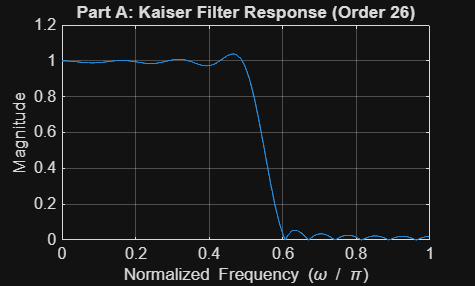


figure(1);
plot(w_rad/pi, magnitude_response);
title(['Part A: Kaiser Filter Response (Order ', num2str(n), ')']);
xlabel('Normalized Frequency (\omega / \pi)');
ylabel('Magnitude');
xlim([0 1]);
ylim([0 1.2]);
grid on;

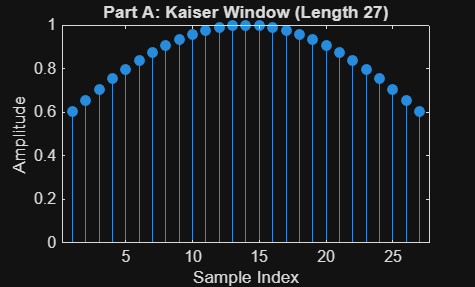


k_window_A = kaiser(n + 1, beta);
figure(2);
stem(k_window_A, 'filled');
title(['Part A: Kaiser Window (Length ', num2str(n + 1), ')']);
xlabel('Sample Index');
ylabel('Amplitude');


% Length of impulse is longer than Part A of Assignment 6 by 9 (18).
% Kaiser windowing is preferable in this case

% Part B
fp = 0.5; %= Passband edge frequency  
fs = 0.6; % Stopband edge frequency
dev_p = 0.05; % Passband tolerance  
dev_s = 0.05; % Stopband tolerance

f_edges = [fp, fs];
mags = [1, 0];
devs = [dev_p, dev_s];

[n, Wn, beta, ftype] = kaiserord(f_edges, mags, devs);
% n: The estimated filter order
% representing the minimum number of taps (or delays)'
% needed to meet the design specifications.

% Wn: This is the normalized cutoff frequency for the filter
% which defines the point halfway between the passband and stopband.

% beta: This is a shape parameter for the Kaiser window that controls the trade-off
% between the stopband attenuation and the transition bandwidth. 

% ftype: This string indicates the filter type to be designed
% such as 'low' for a low-pass filter or 'bandpass' for a bandpass filter

fprintf('The Estimated Filter Order, N: %d\n', n);

The Estimated Filter Order, N: 26


fprintf('The Kaiser Shape Parameter, Beta: %.4f\n', beta);

The Kaiser Shape Parameter, Beta: 1.5099


fprintf('The Length of Impulse Response, N+1: %d\n', n + 1);

The Length of Impulse Response, N+1: 27



% Designing the Filter
b = fir1(n, Wn, kaiser(n + 1, beta));
[h, w_rad] = freqz(b, 1, 1024); magnitude_response = abs(h);

The length of the impulse response is: 27


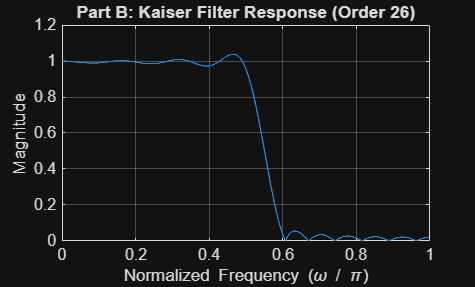


figure(1);
plot(w_rad/pi, magnitude_response);
title(['Part B: Kaiser Filter Response (Order ', num2str(n), ')']);
xlabel('Normalized Frequency (\omega / \pi)');
ylabel('Magnitude');
xlim([0 1]);
ylim([0 1.2]);
grid on;

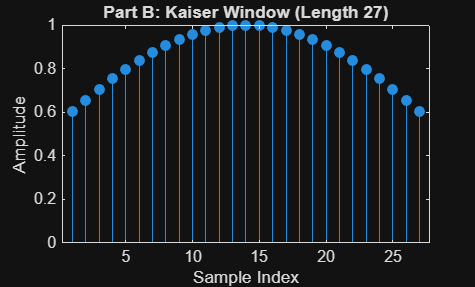


k_window_A = kaiser(n + 1, beta);
figure(2);
stem(k_window_A, 'filled');
title(['Part B: Kaiser Window (Length ', num2str(n + 1), ')']);
xlabel('Sample Index');
ylabel('Amplitude');


% Length of impulse is longer than Part A of Assignment 6 by 5 (22).
% Kaiser windowing is preferable in this case

% Part C
fp = 0.5; %= Passband edge frequency  
fs = 0.555; % Stopband edge frequency
dev_p = 0.05; % Passband tolerance  
dev_s = 0.05; % Stopband tolerance

f_edges = [fp, fs];
mags = [1, 0];
devs = [dev_p, dev_s];

[n, Wn, beta, ftype] = kaiserord(f_edges, mags, devs);
% n: The estimated filter order
% representing the minimum number of taps (or delays)'
% needed to meet the design specifications.

% Wn: This is the normalized cutoff frequency for the filter
% which defines the point halfway between the passband and stopband.

% beta: This is a shape parameter for the Kaiser window that controls the trade-off
% between the stopband attenuation and the transition bandwidth. 

% ftype: This string indicates the filter type to be designed
% such as 'low' for a low-pass filter or 'bandpass' for a bandpass filter

fprintf('The Estimated Filter Order, N: %d\n', n);

The Estimated Filter Order, N: 46


fprintf('The Kaiser Shape Parameter, Beta: %.4f\n', beta);
fprintf('The Length of Impulse Response, N+1: %d\n', n + 1);

The Kaiser Shape Parameter, Beta: 1.5099


The Length of Impulse Response, N+1: 47



% Designing the Filter
b = fir1(n, Wn, kaiser(n + 1, beta));
[h, w_rad] = freqz(b, 1, 1024); magnitude_response = abs(h);

The length of the impulse response is: 47


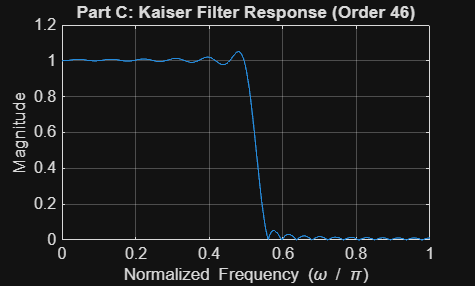


figure(1);
plot(w_rad/pi, magnitude_response);
title(['Part C: Kaiser Filter Response (Order ', num2str(n), ')']);
xlabel('Normalized Frequency (\omega / \pi)');
ylabel('Magnitude');
xlim([0 1]);
ylim([0 1.2]);
grid on;

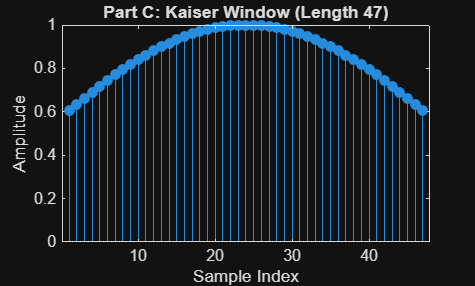


k_window_A = kaiser(n + 1, beta);
figure(2);
stem(k_window_A, 'filled');
title(['Part C: Kaiser Window (Length ', num2str(n + 1), ')']);
xlabel('Sample Index');
ylabel('Amplitude');

% Length of impulse is longer than Part A of Assignment 6 by 7 (40).
% Kaiser windowing is preferable in this case